### Circuito Linea de Tranmision

clear all
Start_Freq=0.1E9;
End_Freq=2E9;
Step=1000;
Z0=50;

netlist_TLfile='NetlistSpice\PasaAltasStubCapacitor.net';
netlistCell=Netlist2CellArray(netlist_TLfile)

netlistCell = 2×7 cell array
    {'SOC1'}    {'N001'}    {'N002'}    {'SOC'}    {[   13.2600]}    {[45]}    {[1.0000e+09]}
    {'L1'  }    {'N002'}    {'0'   }    {'L'  }    {[1.0000e-08]}    {[ 0]}    {[         0]}



% Metodo Objeto Circuito Matlab
SMatlab4=SParametersFromNetlist(netlistCell,Start_Freq,End_Freq,Step,Z0);

Stub =   txlineElectricalLength: ElectricalLength element

                  Name: 'StubOpen'
                    Z0: 13.2600
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'Open'
              StubMode: 'Series'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


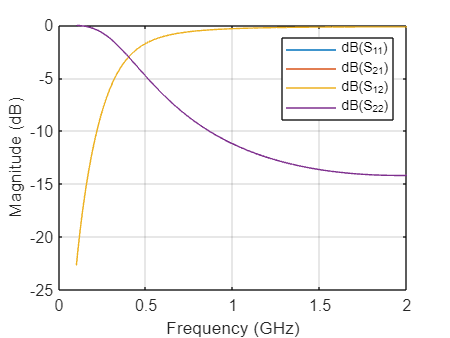

rfplot(SMatlab4);


% Metodo circuito equivalente
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

nuevo_Netlist = 2×7 cell array
    {'SOC1'}    {'N001'}    {'N002'}    {'SOC'}    {[   13.2600]}    {[45]}    {[1.0000e+09]}
    {'L1'  }    {'N002'}    {'0'   }    {'L'  }    {[1.0000e-08]}    {[ 0]}    {[         0]}


Matriz_Z=Z_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
Matriz_S=z2s(Matriz_Z,50);

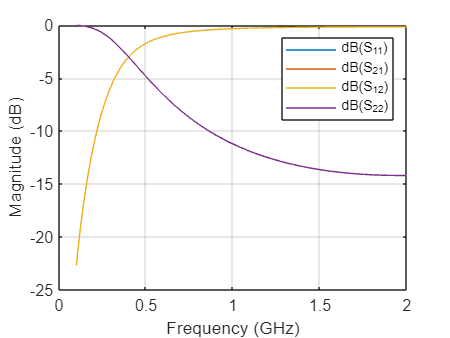


freq=linspace(Start_Freq, End_Freq, Step);
SParamsObject=sparameters(Matriz_S,freq,50);
rfplot(SParamsObject)


% ----- INICIO----------


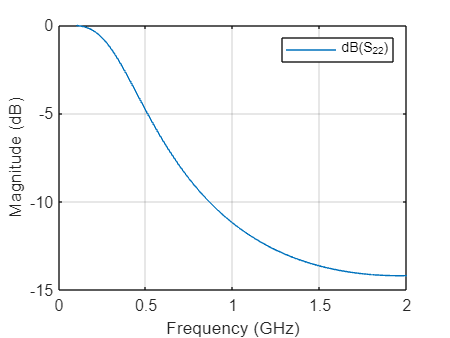


rfplot(SMatlab4,2,2)

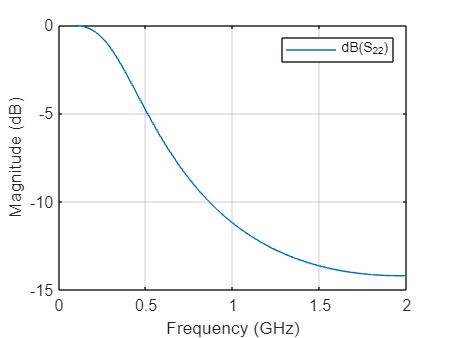

rfplot(SParamsObject,2,2)